**Experiment - 2                                                                                                       Date - 19/1/2024**

**Aim :- Spectral Analysis of discrete-time signals and systems using DTFT **

**Laboratory Exercise **

A) Modify program P3_1 to compute and plot the magnitude and phase spectra of a moving average filter of given Eq. 

For three different values of length M and for 0 <= w <= 2pi . Justify the type of symmetries exhibited by the magnitude and phase spectra . What type of filter does it represent ?

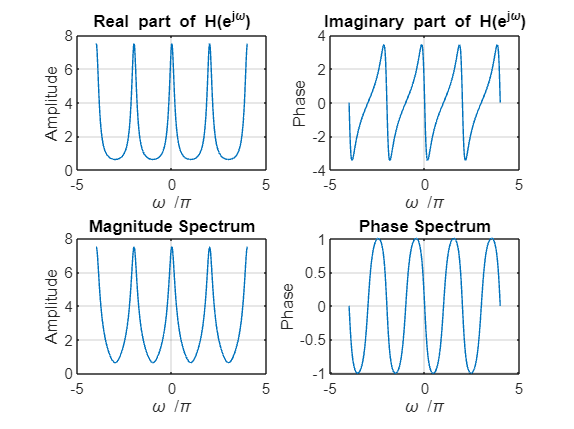

% Program P3_1
% Evaluation of the DTFT
clc ; clear all ; close all ;
% Compute the frequency samples of the DTFT
w = -4*pi:8*pi/511:4*pi;
num = [2 1];den = [1 -0.6];
h = freqz(num, den, w);
% Plot the DTFT
subplot(2,2,1)
plot(w/pi,real(h));grid
title("Real part of H(e^{j\omega})")
xlabel("\omega /\pi");
ylabel("Amplitude");
subplot(2,2,2)
plot(w/pi,imag(h));grid
title("Imaginary part of H(e^{j\omega})")
xlabel("\omega /\pi");
ylabel("Phase");

%|H(e^jw)|
subplot(2,2,3)
plot(w/pi,abs(h));grid
title("Magnitude Spectrum")
xlabel("\omega /\pi");
ylabel("Amplitude");
subplot(2,2,4)
plot(w/pi,angle(h));grid
title("Phase Spectrum")
xlabel("\omega /\pi");
ylabel("Phase");

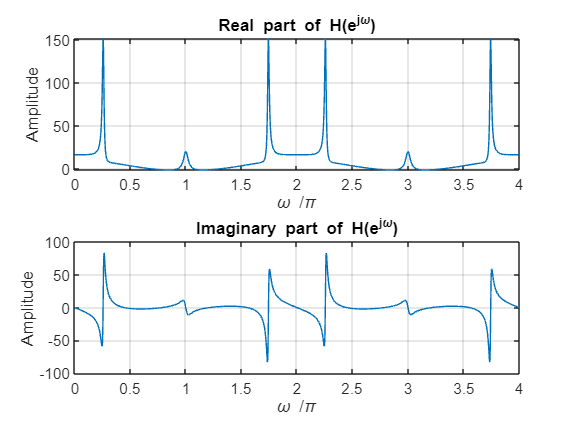

% Modification

% Evaluation of the DTFT
clc ; clear all ; close all ;
% Compute the frequency samples of the DTFT
% M = 5
w = 0 : pi/512 : 4*pi ; num = [2 1 3 5 7] ; den = [1 -0.6 -0.2  1 -0.1] ; h = freqz(num , den , w) ;

% Plot the DTFT
subplot(2,1,1) ; plot(w/pi,real(h)) ; grid
title("Real part of H(e^{j\omega})") ; xlabel("\omega /\pi") ; ylabel("Amplitude") ;

subplot(2,1,2) ; plot(w/pi,imag(h)) ; grid
title("Imaginary part of H(e^{j\omega})") ; xlabel("\omega /\pi") ; ylabel("Amplitude") ;

Here , for M = 5 , both the magnitude and phase spectra are symmetrical about w/pi = 1 .

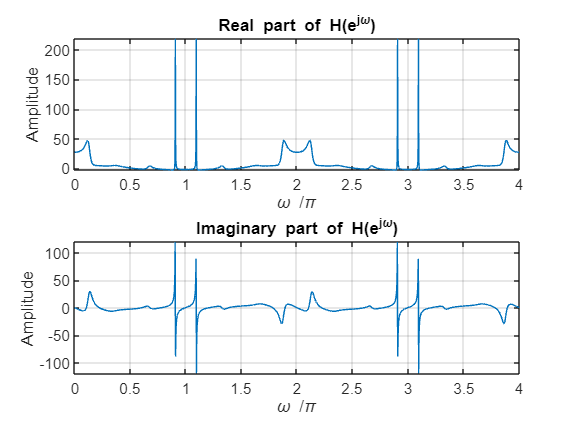

% M = 10
w = 0 : pi/512 : 4*pi ; num = [2 1 3 5 7 4 2 6 9 10] ; den = [1 -0.6 -0.2  1 -0.1 -0.8 -0.2 1 1.2 -0.5] ; h = freqz(num , den , w) ;

% Plot the DTFT
subplot(2,1,1) ; plot(w/pi,real(h)) ; grid on ;
title("Real part of H(e^{j\omega})") ; xlabel("\omega /\pi") ; ylabel("Amplitude") ;

subplot(2,1,2) ; plot(w/pi,imag(h)) ; grid on ;
title("Imaginary part of H(e^{j\omega})") ; xlabel("\omega /\pi") ; ylabel("Amplitude") ;

Here , for M = 10 , both the magnitude and phase spectra are symmetrical about w/pi = 1 .

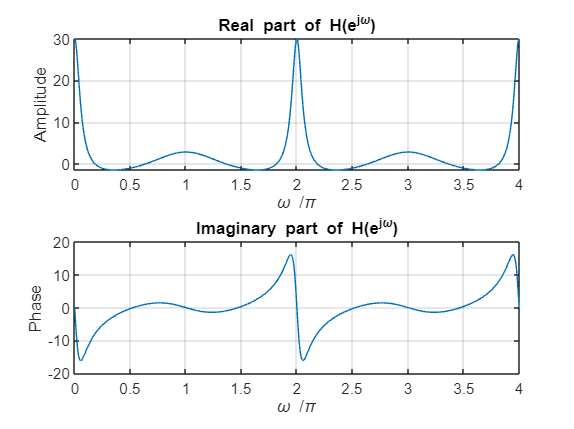

% M = 3
w = 0 : pi/512 : 4*pi ; num = [2 1 3] ; den = [1 -0.6 -0.2] ; h = freqz(num , den , w) ;

% Plot the DTFT
subplot(2,1,1) ; plot(w/pi,real(h)) ; grid on ;
title("Real part of H(e^{j\omega})") ; xlabel("\omega /\pi") ; ylabel("Amplitude") ;

subplot(2,1,2) ; plot(w/pi,imag(h)) ; grid on ;
title("Imaginary part of H(e^{j\omega})") ; xlabel("\omega /\pi") ; ylabel("Phase") ;

Here , for M = 3 , both the magnitude and phase spectra are symmetrical about w/pi = 1 .

Inference :- Here , all the signals are symmetric about w/pi = 1 and repeat after 2pi interval .

B) Write a function named as dtftuser() to compute DTFT for given time domain sequence .

clc ; clear all ; close all ;

%function [H] = dtftuser(num, den, w)
    %N = length(w);
    %H = zeros(size(w));
    %for k = 1:N
        %H(k) = sum(num .* exp(-1i * w(k) * (0:length(num)-1))) / sum(den .* exp(-1i * w(k) * (0:length(den)-1)));
    %end
%end

w = 0 : pi/512 : 4 * pi ; num = [2 1 3] ; den = [1 -0.6 -0.2] ; b = num; a = den;
[H] = dtftuser(b, a, w);
disp(H)

  Columns 1 through 1,724

  30.0000 + 0.0000i  29.9600 - 1.1338i  29.8408 - 2.2592i  29.6439 - 3.3682i  29.3722 - 4.4530i  29.0294 - 5.5066i  28.6202 - 6.5223i  28.1500 - 7.4946i  27.6245 - 8.4187i  27.0500 - 9.2908i  26.4329 -10.1080i  25.7798 -10.8684i  25.0971 -11.5708i  24.3908 -12.2149i  23.6670 -12.8012i  22.9311 -13.3307i  22.1883 -13.8050i  21.4429 -14.2260i  20.6993 -14.5960i  19.9611 -14.9177i  19.2312 -15.1938i  18.5126 -15.4270i  17.8073 -15.6204i  17.1173 -15.7768i  16.4441 -15.8991i  15.7888 -15.9899i  15.1522 -16.0520i  14.5351 -16.0879i  13.9378 -16.1000i  13.3605 -16.0905i  12.8033 -16.0617i  12.2659 -16.0154i  11.7483 -15.9535i  11.2501 -15.8777i  10.7709 -15.7896i  10.3102 -15.6905i   9.8675 -15.5819i   9.4424 -15.4648i   9.0343 -15.3404i   8.6425 -15.2096i   8.2665 -15.0734i   7.9057 -14.9325i   7.5596 -14.7878i   7.2275 -14.6398i   6.9089 -14.4891i   6.6032 -14.3363i   6.3099 -14.1819i   6.0285 -14.0262i   5.7584 -13.8697i   5.4991 -13.7127i   5.2502 -13.5555i   5

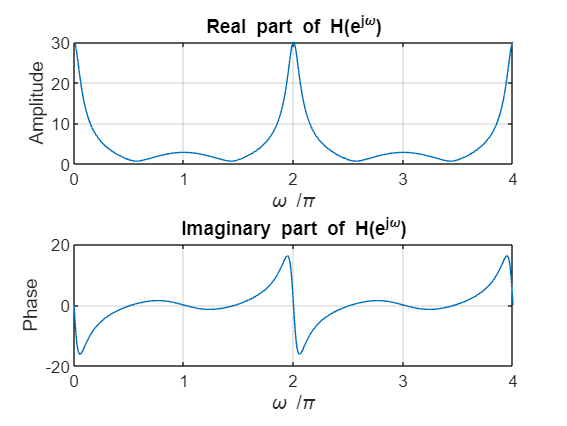

subplot(2,1,1) ; plot(w/pi,abs(H)) ; grid on ;
title("Real part of H(e^{j\omega})") ; xlabel("\omega /\pi") ; ylabel("Amplitude") ;
subplot(2,1,2) ; plot(w/pi,imag(H)) ; grid on ;
title("Imaginary part of H(e^{j\omega})") ; xlabel("\omega /\pi") ; ylabel("Phase") ;

Inference :- Here , we learnt to implement a **Matlab Function dtftuser() similar to freqz() **and observing the output we can say that the output is similar to what output was reflected by freqz() funnction in the first case .

C) Compute and plot the frequency response of the following system . Based on your plots , comment on what kind of system this is (lowpass , highpass , etc.).

y[n] + 2.37y[n − 1] + 2.7y[n − 2] + 1.6y[n − 3] + 0.41y[n − 4] =

 0.08x[n] − 0.033x[n − 1] + 0.05x[n − 2] − 0.033x[n − 3] + 0.008x[n − 4]

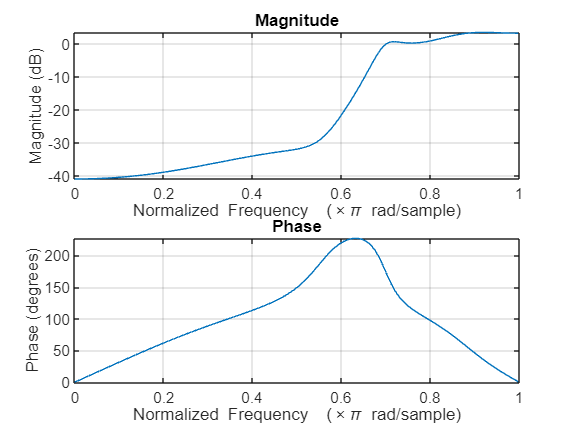

a = [1 2.37 2.7 1.6 0.41] ; b = [0.08 -0.033 0.05 -0.033 0.008] ;
freqz(b,a)

Comment :- By observation of magnitude spectrum , we ca say that it is **high pass system** as it allows higher frequencies to pass thorugh it . 

**Conclusion : - In this experiment , we learnt to plot the frequency response of discrete - time signals and systems . We also learnt to replicate inbuilt functions by user defined functions and learnt to determine the type of the system (lowpass , highpass , etc.) by visualizing the graphs .**